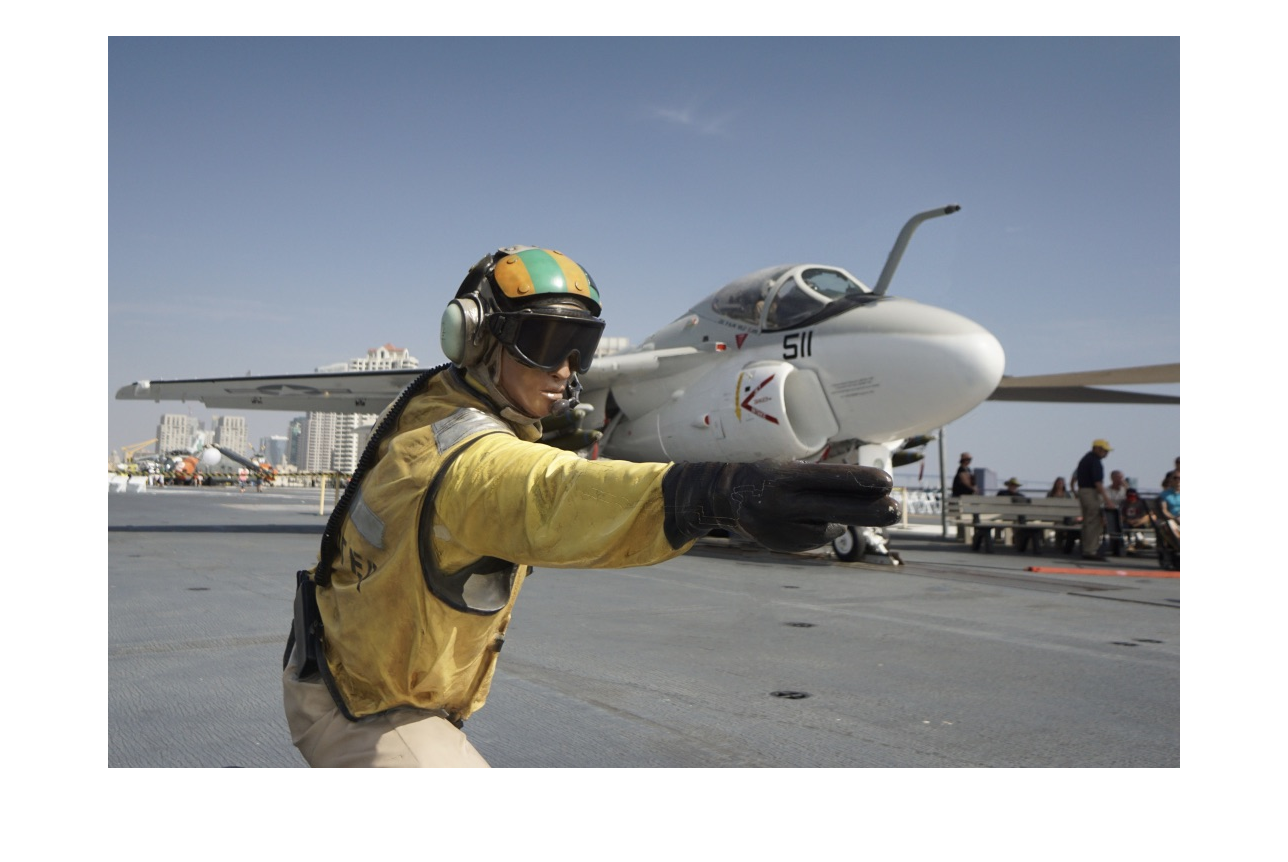

%convert the image to YUV type
[pilot] = imread('pilot.tiff');
[key] = imread('baseball.tiff');

imshow(pilot);


[row,col,channel]=size(pilot);
key = imresize(key,[row,col]);

%YUV should be value in [0,255]
pilot_YUV=rgb2ycbcr(pilot);
key_YUV = rgb2ycbcr(key);

key_dct=zeros(row,col,channel);
RLencode={[],[],[]};
DC_matrix={[],[],[]};

quatization_matrix=[
[16,11,10,16,24,40,51,61]
[12,12,14,19,26,58,60,55]
[14,13,16,24,40,57,69,56]
[14,17,22,29,51,87,80,62]
[18,22,37,56,68,109,103,77]
[24,35,55,64,81,104,113,92]
[49,64,78,87,103,121,120,101]
[72,92,95,98,112,100,103,99]];

%y=encode(quatization_matrix)
% slice each part into 8*8 matrix, do dct,quantization,encode
for i=1:row/8
    for j=1:col/8
        for k=1:channel
            downsample_pilot=pilot_YUV(8*i-7:8*i,8*j-7:8*j,k);
            downsample_key = key_YUV(8*i-7:8*i,8*j-7:8*j,k);
            % for each 8*8 input matrix apply dct
            key_dct(8*i-7:8*i,8*j-7:8*j,k) = dct2(downsample_key);
            pilot_dct=dct2(downsample_pilot)*0.5+key_dct(8*i-7:8*i,8*j-7:8*j,k)*0.5;
            %divide by quantization matrix
            pilot_qua=round(pilot_dct./quatization_matrix);
            %zigzag & Run length encode
            [DC,pilot_encode,RLcode]=encode(pilot_qua);
            % for each channel, run length encode link into a vector, store each DC term in another array 
            DC_matrix{k}=[DC_matrix{k},DC];
            RLencode{k}=[RLencode{k},RLcode];
        end
    end
end

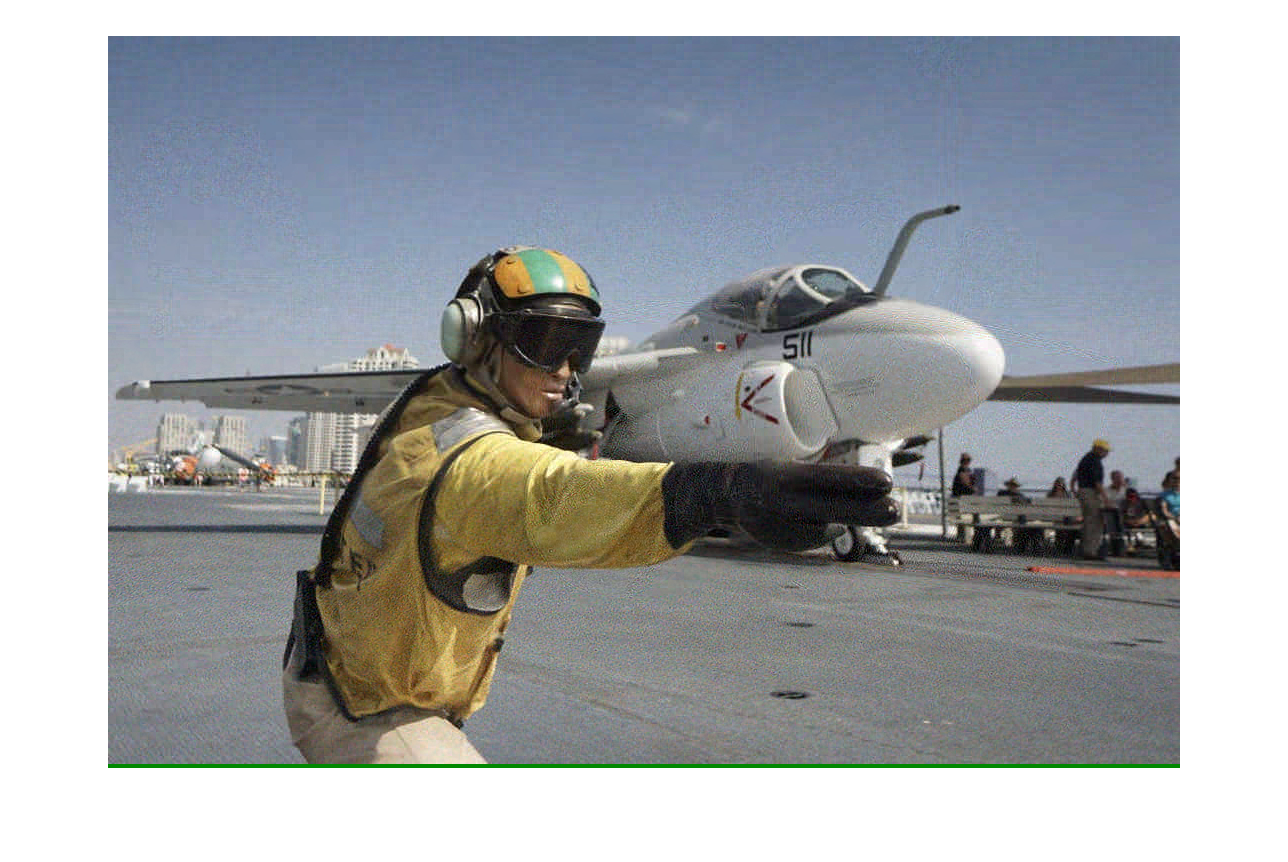

DC_cell = [];
AC_cell = [];
recover_decode = zeros(row,col,channel);
recover_quantization = zeros(row,col,channel);
recover_dct = zeros(row,col,channel);

for k=1:channel
    DC_cell = DC_matrix{k};
    AC_cell = RLencode{k};
    for i=1:row/8
        for j = 1:col/8
            if ~isempty(DC_cell) && ~isempty(AC_cell)
                [AC,AC_cell] = crop_AC (AC_cell);
                decode_temp = decode(DC_cell(1),AC);
                DC_cell(1)=[];
                decode_temp = decode_temp .* quatization_matrix;
                % This step recover the effect of key
                decode_temp = (decode_temp - 0.5*key_dct(8*i-7:8*i,8*j-7:8*j,k))*2;
                recover_dct(8*i-7:8*i,8*j-7:8*j,k) = idct2(decode_temp);
            end
        end
    end
end

recover_dct = uint8(recover_dct);
recover_pilot=ycbcr2rgb(recover_dct);

imshow(recover_pilot);